## Image segmentation using region growing

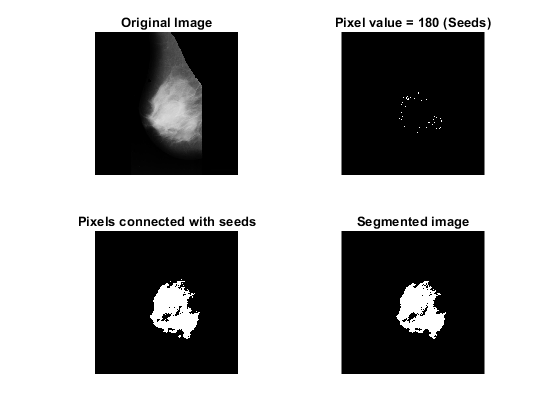

     1921048        4532
        4532      162946



       Contrast: 0.0043
    Correlation: 0.9706
         Energy: 0.8485
    Homogeneity: 0.9978



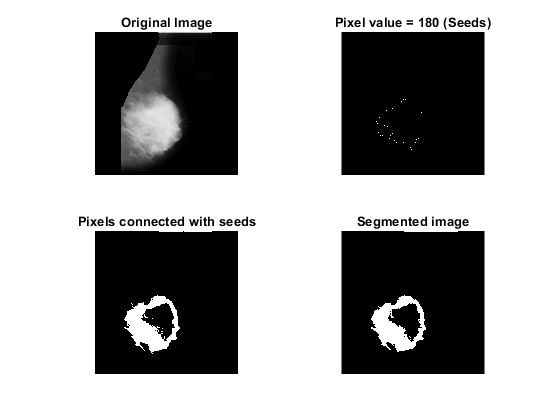

     1937846        3749
        3749      147714



       Contrast: 0.0036
    Correlation: 0.9733
         Energy: 0.8622
    Homogeneity: 0.9982



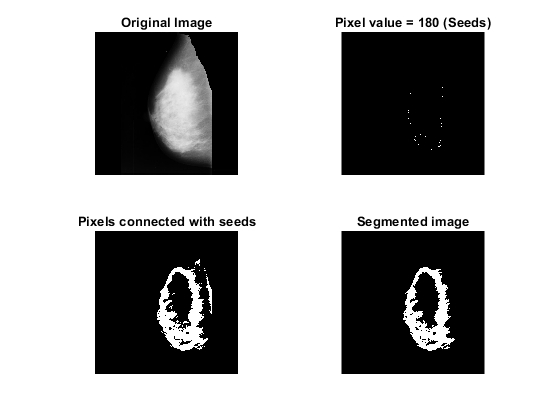

     1900124        7385
        7385      178164



       Contrast: 0.0071
    Correlation: 0.9563
         Energy: 0.8314
    Homogeneity: 0.9965



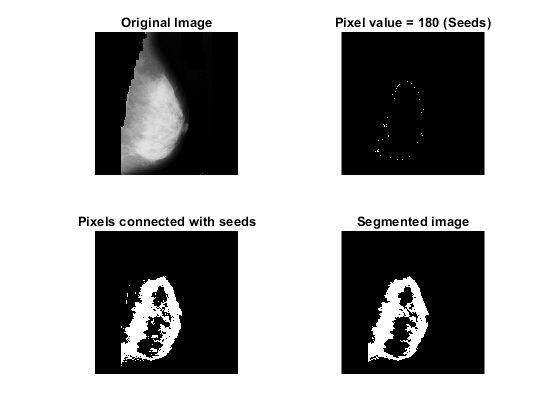

     1835792        8070
        8070      241126



       Contrast: 0.0077
    Correlation: 0.9632
         Energy: 0.7826
    Homogeneity: 0.9961



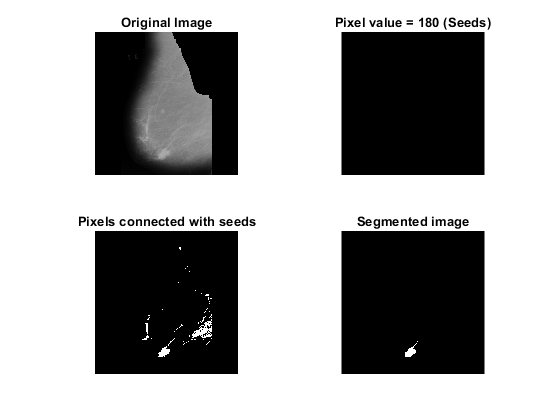

     2083822         656
         656        7924



       Contrast: 6.2683e-04
    Correlation: 0.9232
         Energy: 0.9912
    Homogeneity: 0.9997



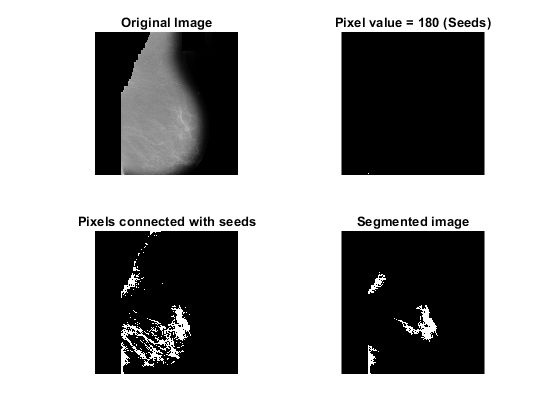

     2018482        6096
        6096       62384



       Contrast: 0.0058
    Correlation: 0.9080
         Energy: 0.9309
    Homogeneity: 0.9971



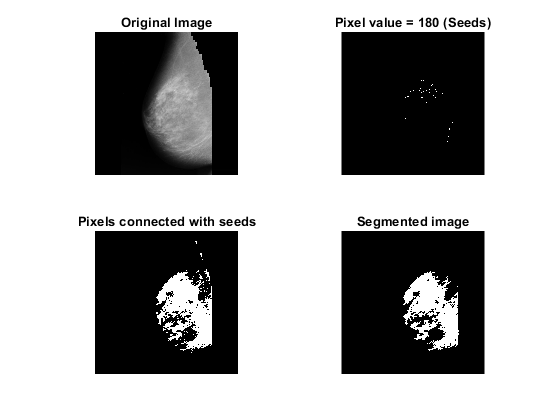

     1833064       11291
       11291      237412



       Contrast: 0.0108
    Correlation: 0.9485
         Energy: 0.7799
    Homogeneity: 0.9946



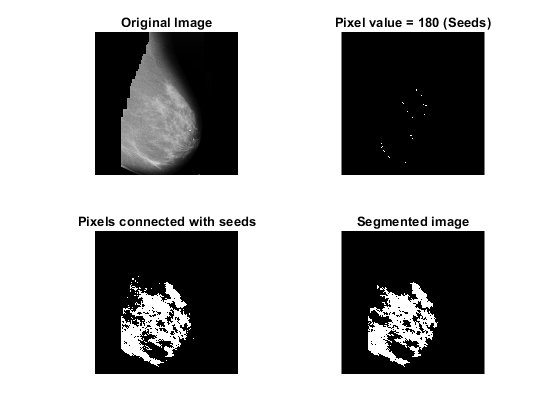

     1812586       13486
       13486      253500



       Contrast: 0.0129
    Correlation: 0.9421
         Energy: 0.7647
    Homogeneity: 0.9936



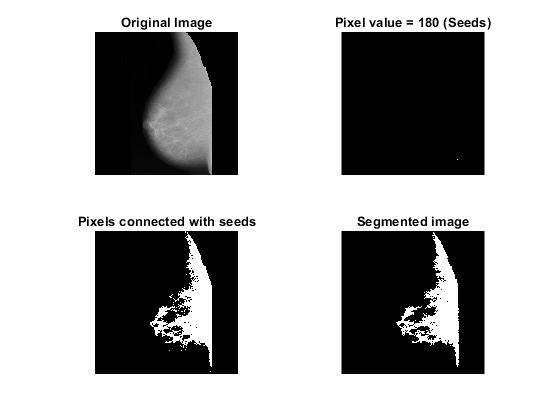

     1802862       12012
       12012      266172



       Contrast: 0.0115
    Correlation: 0.9502
         Energy: 0.7582
    Homogeneity: 0.9943



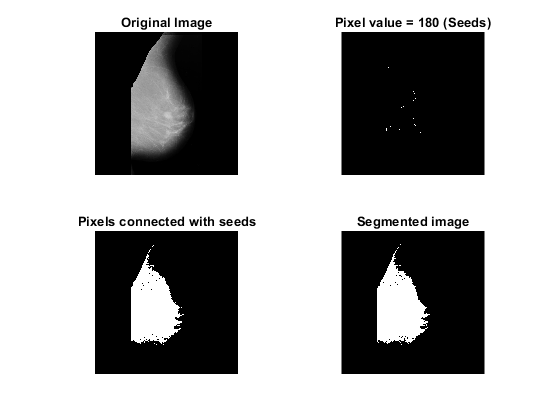

     1789862        4742
        4742      293712



       Contrast: 0.0045
    Correlation: 0.9815
         Energy: 0.7510
    Homogeneity: 0.9977



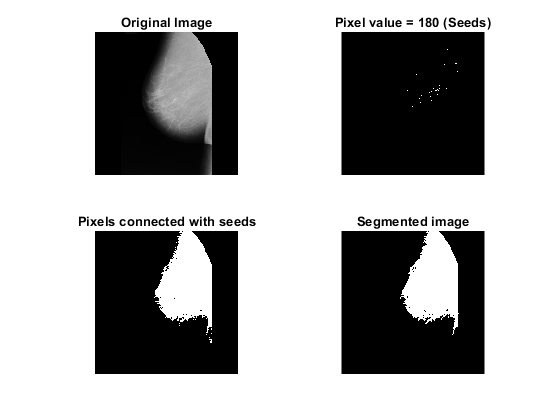

     1709430        5052
        5052      373524



       Contrast: 0.0048
    Correlation: 0.9837
         Energy: 0.6989
    Homogeneity: 0.9976



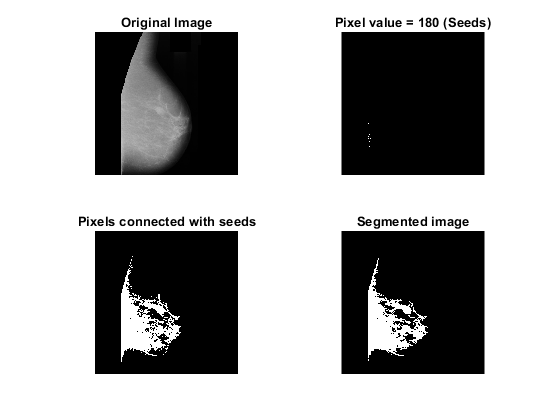

     1857156       11200
       11200      213502



       Contrast: 0.0107
    Correlation: 0.9442
         Energy: 0.7978
    Homogeneity: 0.9946



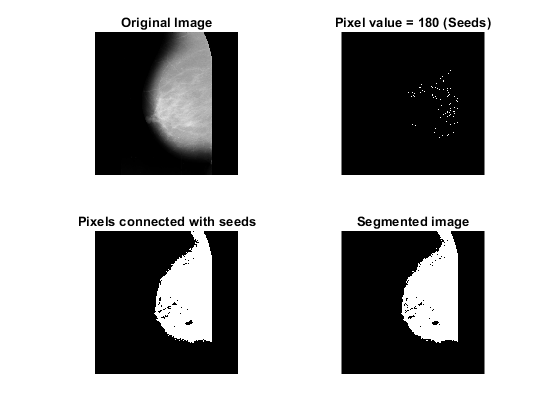

     1632716        6194
        6194      447954



       Contrast: 0.0059
    Correlation: 0.9826
         Energy: 0.6543
    Homogeneity: 0.9970



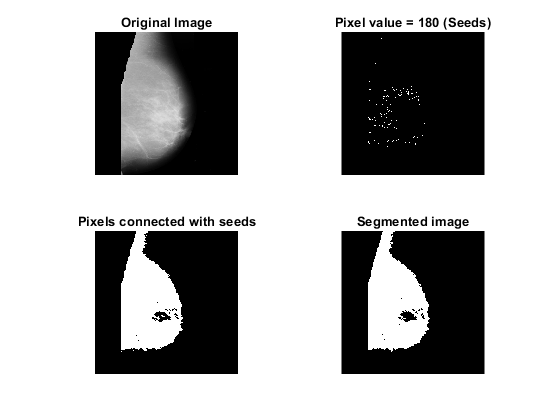

     1589676        4456
        4456      494470



       Contrast: 0.0043
    Correlation: 0.9883
         Energy: 0.6327
    Homogeneity: 0.9979



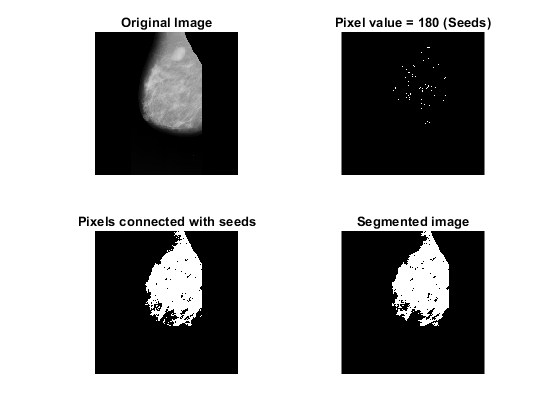

     1745690        8146
        8146      331076



       Contrast: 0.0078
    Correlation: 0.9713
         Energy: 0.7207
    Homogeneity: 0.9961



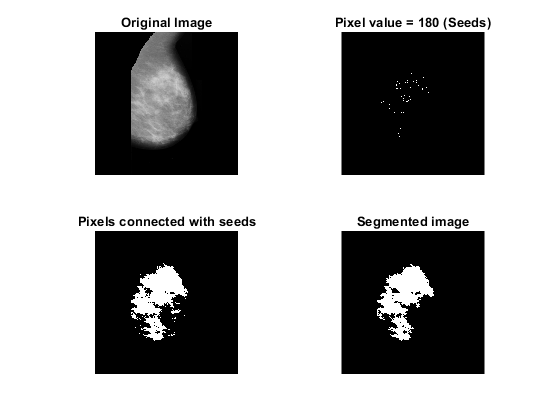

     1888628        6086
        6086      192258



       Contrast: 0.0058
    Correlation: 0.9661
         Energy: 0.8227
    Homogeneity: 0.9971



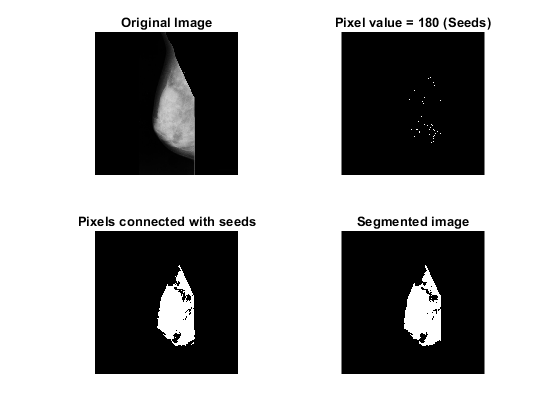

     1899960        3859
        3859      185380



       Contrast: 0.0037
    Correlation: 0.9776
         Energy: 0.8318
    Homogeneity: 0.9982



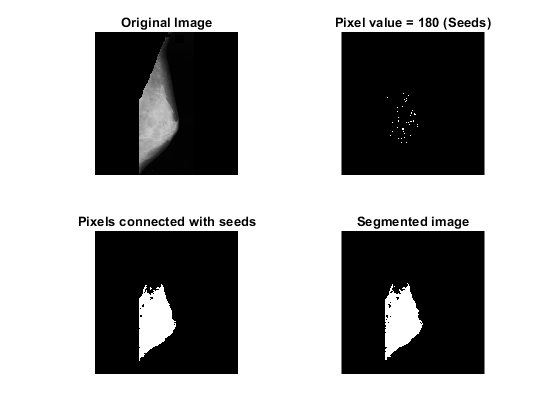

     1906962        2814
        2814      180468



       Contrast: 0.0027
    Correlation: 0.9832
         Energy: 0.8375
    Homogeneity: 0.9987



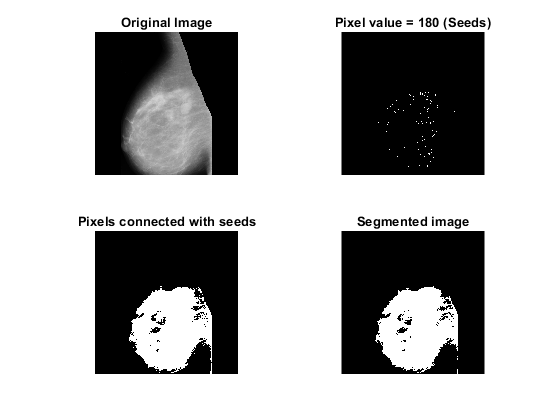

     1586734        9677
        9677      486970



       Contrast: 0.0092
    Correlation: 0.9745
         Energy: 0.6289
    Homogeneity: 0.9954



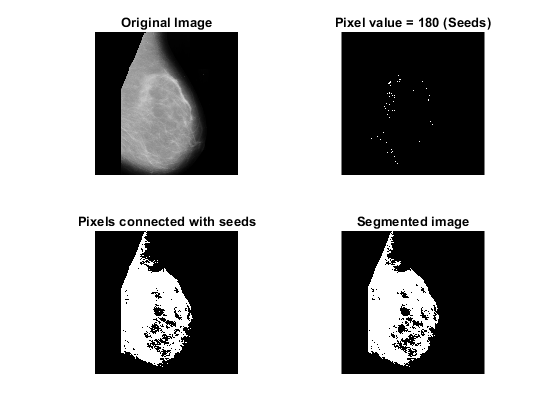

     1558070       15635
       15635      503718



       Contrast: 0.0149
    Correlation: 0.9600
         Energy: 0.6122
    Homogeneity: 0.9925



%img="new/mdb001.tiff";

%put images file location here
breastImds = imageDatastore(...
    "C:\Users\Daniel Kee\Documents\Monash\FYP\FIT3162\fit3162\Code\MIAS(no muscle)");
%img="MIAS(no muscle)/mdb020.jpg";

condition = ['B';'B';'N';'N';'B';'N';'N';'N';'N';'B';'N';'B';'B';...
    'N';'B';'N';'B';'N';'B';'N';];
final = [];
j = 1;

%loop through the images
while(hasdata(breastImds))
    I = read(breastImds);
    I = rgb2gray(I);

    I = double(I);
    figure, subplot(2,2,1),imshow(uint8(I)),title('Original Image');
    Seeds = [180];
    SI = I == Seeds;
    subplot(2,2,2), imshow(SI, []),title('Pixel value = 180 (Seeds)');
    T = 30;
    TI = false(size(I));

    for i = 1:length(Seeds)
        seed_val = Seeds(i);
        S = abs(I-seed_val) <= T;
        TI = TI | S;
    end

    subplot(2,2,3), imshow(TI, []),title('Pixels connected with seeds');
    IM = imreconstruct(SI,TI);
    subplot(2,2,4), imshow(IM, []),title('Segmented image');
    
    
    [GLCM, SI] = graycomatrix(IM,'Offset',[1 1],'NumLevels',2,'GrayLimits',[],'Symmetric', true);
    stats = graycoprops(GLCM,'all');
    disp(GLCM);
    disp(stats);
    cell = struct2cell(stats);
    flipCell = transpose(cell);
    rowToAdd = [flipCell condition(j,1)];
    adding = [final;rowToAdd];
    final = adding;
    j = j+1;
end


Table = table(final);
filename = 'results.xlsx';
writetable(Table,filename,'Sheet',1,'Range','B3');
finalTable = readtable(filename);
finalTable.Properties.VariableNames{'final_1'} = 'Contrast';
finalTable.Properties.VariableNames{'final_2'} = 'Correlation';
finalTable.Properties.VariableNames{'final_3'} = 'Energy';
finalTable.Properties.VariableNames{'final_4'} = 'Homogeneity';
finalTable.Properties.VariableNames{'final_5'} = 'Actual Condition';
writetable(finalTable,filename,'Sheet',1,'Range','B3');